% #1.
clear
L=0.1 % Гн

L = 0.1000

syms t
u_L=141*sin(1000*t-30*pi/180)

$$u\_L = 141\,\sin\left(1000\,t-\frac{\pi }{6}\right)$$

U_m=141

U_m = 141

omega=1000

omega = 1000

psi_U=-pi/6

psi_U = -0.5236

X_L=L*omega

X_L = 100

psi_I=psi_U-pi/2

psi_I = -2.0944

I_m=U_m/X_L

I_m = 1.4100

i_L=I_m*sin(omega*t+psi_I)

$$i\_L = \frac{141\,\sin\left(1000\,t-\frac{2\,\pi }{3}\right)}{100}$$

% #2.
clear
C=0.1 % мкФ

C = 0.1000

syms t
i=0.1*sin(400*t+pi/3)

$$i = \frac{\sin\left(400\,t+\frac{\pi }{3}\right)}{10}$$

I_m=0.1

I_m = 0.1000

omega=400

omega = 400

psi_I=pi/3

psi_I = 1.0472

X_C=1/(omega*C*1e-6)

X_C = 2.5000e+04

U_m=I_m*X_C

U_m = 2.5000e+03

psi_U=psi_I+pi/2

psi_U = 2.6180

u=U_m*sin(omega*t+psi_U)

$$u = 2500\,\sin\left(400\,t+\frac{5\,\pi }{6}\right)$$

% #3.
clear
digits(3)
R=160 % Ом

R = 160

C=26.54 % мкФ

C = 26.5400

syms t
i=0.1*sin(314*t)

$$i = \frac{\sin\left(314\,t\right)}{10}$$

I_m=0.1

I_m = 0.1000

omega=314

omega = 314

psi_I=0

psi_I = 0

X_C=round(1/(omega*C*1e-6))

X_C = 120

Z=sqrt(R^2+X_C^2)

Z = 200

phi=atan(-X_C/R)*180/pi

phi = -36.8699

psi_U=psi_I+phi

psi_U = -36.8699

U_m=I_m*Z

U_m = 20

u=U_m*sin(omega*t+vpa(psi_U*pi/180))

$$u = 20\,\sin\left(314\,t-0.644\right)$$

% #4. Для синусоидальных токов уравнения идеальных элементов RLC
syms I_m omega t psi_i R L C tau u_C0
i(t)=I_m*sin(omega*t+psi_i)

$$i(t) = I_{m}\,\sin\left(\psi_{i}+\omega \,t\right)$$

u_R=R*i

$$u\_R(t) = I_{m}\,R\,\sin\left(\psi_{i}+\omega \,t\right)$$

u_L=L*diff(i), u_L=omega*L*I_m*sin(omega*t+psi_i+pi/2)

$$u\_L(t) = I_{m}\,L\,\omega \,\cos\left(\psi_{i}+\omega \,t\right)$$

$$u\_L = I_{m}\,L\,\omega \,\sin\left(\psi_{i}+\frac{\pi }{2}+\omega \,t\right)$$

u_C=1/C*int(i(tau),tau,0,t)+u_C0, u_C=1/(omega*C)*I_m*sin(omega*t+psi_i-pi/2)

$$u\_C = u_{\mathrm{C0}}-\frac{I_{m}\,\left(\cos\left(\psi_{i}+\omega \,t\right)-\cos\left(\psi_{i}\right)\right)}{C\,\omega }$$

$$u\_C = \frac{I_{m}\,\sin\left(\psi_{i}-\frac{\pi }{2}+\omega \,t\right)}{C\,\omega }$$

syms R L C I phi phi_u phi_i omega U_R U_C U_L
U_R==R*I, phi==phi_u-phi_i, phi==0

$$ans = U_{R}=\text{I}\,R$$

$$ans = \varphi =\varphi_{u}-\varphi_{i}$$

$$ans = \varphi =0$$

U_L==omega*L*I, phi==phi_u-phi_i, phi==pi/2

$$ans = U_{L}=\text{I}\,L\,\omega$$

$$ans = \varphi =\varphi_{u}-\varphi_{i}$$

$$ans = \varphi =\frac{\pi }{2}$$

U_C==1/(omega*C)*I, phi==phi_u-phi_i, phi==-pi/2

$$ans = U_{C}=\frac{\text{I}}{C\,\omega }$$

$$ans = \varphi =\varphi_{u}-\varphi_{i}$$

$$ans = \varphi =-\frac{\pi }{2}$$

% #5.
% Угол сдвига фаз
syms phi psi_i psi_u
phi==psi_u-psi_i

$$ans = \varphi =\psi_{u}-\psi_{i}$$

% #6.
% Действующее значение периодического тока
syms t T i(t) R I I_m omega
I==sqrt(1/T*int(i^2,t,0,T))

$$ans = \text{I}=\sqrt{\frac{\int_{0}^{T}{i\left(t\right)}^{2}\mathrm{d}t}{T}}$$

% Действующее значение син.тока
I==I_m/sqrt(2)

$$ans = \text{I}=\frac{\sqrt{2}\,I_{m}}{2}$$

% Действующие значения син.напряжений и ЭДС
syms U U_m E E_m
U==U_m/sqrt(2), E==E_m/sqrt(2)

$$ans = U=\frac{\sqrt{2}\,U_{m}}{2}$$

$$ans = \text{E}=\frac{\sqrt{2}\,E_{m}}{2}$$

% #7.
clear
% Физическая величина, численно равная среднему значению от произведе-
% ния мгновенных значений напряжения u(t) и тока i(t) , называется активной
% мощностью Р. По определению имеем:
syms u(t) i(t) T t U_m I_m phi omega
P=1/T*int(u*i,t,0,T)                 % активная мощность (Вт)

$$P = \frac{\int_{0}^{T}i\left(t\right)\,u\left(t\right)\mathrm{d}t}{T}$$

P=subs(P,[u i],[U_m*sin(omega*t) I_m*sin(omega*t-phi)])

$$P = \frac{I_{m}\,U_{m}\,\left(\frac{T\,\cos\left(\varphi \right)}{2}+\frac{\frac{\sin\left(\varphi -2\,T\,\omega \right)}{4}-\frac{\sin\left(\varphi \right)}{4}}{\omega }\right)}{T}$$

P=subs(P,omega,2*pi/T)

$$P = \frac{I_{m}\,U_{m}\,\cos\left(\varphi \right)}{2}$$

% #8.
% Расчетные величины
clear
syms P S Q P_max U I phi
S==P_max, S==U*I              % полная мощность (ВА)

$$ans = S=P_{\max}$$

$$ans = S=\text{I}\,U$$

Q==U*I*sin(phi)               % реактивная мощность (ВАр)

$$ans = Q=\text{I}\,U\,\sin\left(\varphi \right)$$

S==sqrt(P^2+Q^2)

$$ans = S=\sqrt{P^{2}+Q^{2}}$$

k_m=P/S, k_m=cos(phi)

$$k\_m = \frac{P}{S}$$

$$k\_m = \cos\left(\varphi \right)$$

% #9.
clear
syms U phi U_R U_X I I_G I_B
% Проекция напряжения на линию тока
U_R==U*cos(phi)  % называется активной составляющей напряжения

$$ans = U_{R}=U\,\cos\left(\varphi \right)$$

% Проекция напряжения на линию, перпендикулярную току,
U_X==U*sin(phi)  % называется реактивной составляющей напряжения

$$ans = U_{X}=U\,\sin\left(\varphi \right)$$

% Проекция тока на линию напряжения
I_G==I*cos(phi)  % называется активной составляющей тока

$$ans = I_{G}=\text{I}\,\cos\left(\varphi \right)$$

% Проекция тока на линию, перпендикулярную напряжению,
I_B==I*sin(phi)  % называется реактивной составляющей тока

$$ans = I_{B}=\text{I}\,\sin\left(\varphi \right)$$

% Имеют место очевидные соотношения:
U==sqrt(U_R^2+U_X^2), I== sqrt(I_G^2+I_B^2)

$$ans = U=\sqrt{{U_{R}}^{2}+{U_{X}}^{2}}$$

$$ans = \text{I}=\sqrt{{I_{B}}^{2}+{I_{G}}^{2}}$$

% #10.
clear
syms Z U I I_G I_B R_ek X_ek U_R U_X X_L X_C Y G_ek B_ek B_L B_C phi
% В цепи синусоидального тока для пассивного двухполюсника 
% по определению вводятся следующие величины:
% 1. Полное сопротивление Z:
Z==U/I

$$ans = Z=\frac{U}{\text{I}}$$

% 2. Эквивалентные активное Rэк и реактивное Xэк сопротивления:
R_ek==U_R/I, X_ek==U_X/I, X_ek==X_L-X_C

$$ans = R_{\mathrm{ek}}=\frac{U_{R}}{\text{I}}$$

$$ans = X_{\mathrm{ek}}=\frac{U_{X}}{\text{I}}$$

$$ans = X_{\mathrm{ek}}=X_{L}-X_{C}$$

% #11.
clear
syms Z U I I_G I_B R_ek X_ek U_R U_X X_L X_C Y G_ek B_ek B_L B_C phi
% В цепи синусоидального тока для пассивного двухполюсника 

% 3. Полная проводимость Y :
Y==I/U

$$ans = Y=\frac{\text{I}}{U}$$

% 4. Эквивалентные активная эк G и реактивная эк B проводимости:
G_ek==I_G/U, B_ek==I_B/U, B_ek==B_L-B_C

$$ans = G_{\mathrm{ek}}=\frac{I_{G}}{U}$$

$$ans = B_{\mathrm{ek}}=\frac{I_{B}}{U}$$

$$ans = B_{\mathrm{ek}}=B_{L}-B_{C}$$

% #12.
% Электрическая цепь по схеме рис. 1. 5 должна содержать амперметр А и
% вольтметр U для измерения действующих значений напряжения и тока, фазо-
% метр phi для измерения угла сдвига фаз между мгновенными значениями напря-
% жения и тока на входе пассивного двухполюсника П.
% Угол сдвига фаз пассивного двухполюсника -pi/2<=phi<=pi/2

% #13.
R=1000 % Ом

R = 1000

L=0.12 % Гн

L = 0.1200

U_R=10 % В

U_R = 10

f=1000 % Гц

f = 1000


I=U_R/R

I = 0.0100

X_L=round(L*2*pi*f)

X_L = 754

Z=sqrt(R^2+X_L^2)

Z = 1.2524e+03

U=I*Z

U = 12.5240

% #14
R=160 % Ом

R = 160

X=120 % Ом

X = 120

U=20 % В

U = 20


Z=sqrt(R^2+X^2)

Z = 200

I=U/Z

I = 0.1000

U_R=R*I

U_R = 16

P=U_R*I

P = 1.6000

% #15 % Рис.1.14

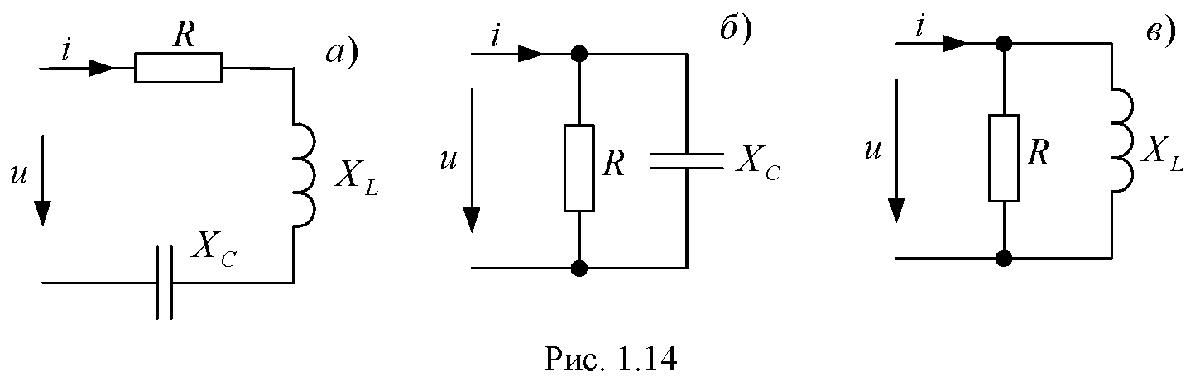

U=100 % В

U = 100

R=80 % Ом

R = 80

X_L=100 % Ом

X_L = 100

X_C=60 % Ом

X_C = 60


% а)
X_ek=X_L-X_C

X_ek = 40

Z=round(sqrt(R^2+X_ek^2))

Z = 89

I=U/Z

I = 1.1236

% б)
G_ek=1/R

G_ek = 0.0125

B_ek=1/X_C

B_ek = 0.0167

Y=sqrt(G_ek^2+B_ek^2)

Y = 0.0208

I=U*Y

I = 2.0833

% в)
G_ek=1/R

G_ek = 0.0125

B_ek=1/X_L

B_ek = 0.0100

Y=sqrt(G_ek^2+B_ek^2)

Y = 0.0160

I=U*Y

I = 1.6008

% #16
U=10 % В

U = 10

I=2 % А

I = 2

phi=-30*pi/180

phi = -0.5236

Z=U/I

Z = 5

R_ek=Z*cos(phi)

R_ek = 4.3301

X_ek=Z*sin(phi)

X_ek = -2.5000